# Práctica 1: análisis de sonidos

## 0. Repaso de Matlab

Antes de empezar la práctica es **MUY IMPORTANTE** tener unos conocimientos básicos de Matlab y manejar con soltura ciertos conceptos. En caso de tener dificultades para completar esta sección, se recomienda buscar un tutorial más detallado.

Recuerda, antes de empezar, lo siguiente:

- Matlab es un entorno de programación donde no hay compilación previa. Compila cuando se intenta ejecutar el código.

- Cuando se intenta ejecutar algo, primero va compilando el código, por lo que pueden aparecer ERRORES DE COMPILACIÓN. Hay que leer siempre los mensajes de error en rojo, ya que el 90% de las veces nos dan directamente la solución.

- Si no hay errores de compilación, al ejecutar el código pueden aparecer ERRORES DE EJECUCIÓN. Hay que leer siempre los mensajes de error en rojo, ya que el 90% de las veces nos dan pistas sobre cómo solucionarlo.

- Si no hay errores de compilación ni de ejecución, pueden aparecer ERRORES DEL ALGORITMO que usamos. Es decir, el programa se ejecuta correctamente pero no hace lo que queremos. 

- Para la detección de errores y su depuración (DEBUGGING), es recomendable usar BREAKPOINTS, que detienen la ejecución justo antes de ejecutar la línea donde están, y nos dan control en la ventana de comandos (*K>>*) . Para ayudar en la depuración, también se pueden usar salidas por consola (*disp()*), por ejemplo.

Con respecto al uso de ChatGPT y aplicaciones similares de IA generativa. Obviamente, se pueden usar. Pero, ojo:

- Primer problema: no vais a tener siempre ChatGPT "a vuestro lado". Si no entendéis lo que propone ChatGPT, no vais a ser capaces de hacerlo sin su ayuda y **hay pruebas en las que no podréis usarlo**.

- Segundo problema: ¿sabéis cómo se generan las soluciones del ChatGPT? Es una IA GENERATIVA. Es decir, usando una enorme cantidad de datos siempre os intenta dar una respuesta. Si lo que se le pregunta es sencillo y tiene suficientes datos donde haya respuestas válidas, probablemente es capaz de encontrar la solución a lo que se le pregunta. Pero, habitualmente, siempre quiere dar una solución, por lo que hay veces que INVENTA con los datos que tiene. Por eso es vital ser crítico con ChatGPT y **siempre entender lo que propone**, para ver si es lo que realmente queremos.

- Plantear una solución generada a partir de una IA generativa sin entender cómo funciona, paso a paso, se considerará una respuesta nula en la prueba correspondiente.

### 0.1 Generación de vectores

Escribe el código para generar un vector columna que comience en 0 y que contenga 5000 elementos equiespaciados, con paso de 0.2. Este será nuestro vector de tiempos. Compara tu resultado con la variable timeVectorOK y comprueba que son iguales.

% INSERTE EL CÓDIGO AQUÍ:
N = 5000; % número de elementos
step = 0.2; % distancia entre elementos
timeVector = (0:step:(N-1)*step).';

### 0.2 Bucle for y manejo de índices

Escribe el código para calcular el valor medio de cada elemento y sus S sucesores (media local *desplazada *con S elementos) de la variable *noise* usando un bucle for. ¿Cuántos elementos tiene el vector de medias calculado? Nota: comienza con valores N y S pequeños si tienes dificultad con los índices.

% %N = 20: Define el número de muestras de la señal de ruido.
% noise = randn(N,1): Genera una señal de ruido blanco con N muestras, donde cada muestra es un número aleatorio con distribución normal (media 0 y varianza 1).
% S = 5: Define el tamaño de la ventana para calcular la media móvil.

% Este bucle for recorre la señal de ruido y calcula la media móvil para cada ventana de tamaño S. 
% La variable index recorre desde 1 hasta N-S para asegurar que la ventana no exceda los límites de la señal. En cada iteración:
% 
% mean(noise(index:1:index+S)): Calcula la media de los valores de noise desde la posición index hasta index+S.
% meanVector(index): Almacena el valor de la media calculada en el vector meanVector.
% Finalmente, el código devuelve el vector meanVector, que contiene las medias móviles calculadas para cada ventana de la señal de ruido.


% INSERTE EL CÓDIGO AQUÍ:
N = 20;
noise = randn(N,1);
S = 5;
for index = 1:N-S 
  meanVector(index) = mean(noise(index:1:index+S));
end

meanVector

meanVector =     0.1767    0.1897    0.2044    0.0192   -0.0563   -0.1675    0.0269   -0.1626   -0.0863   -0.1779   -0.3493   -0.2926   -0.6187   -0.2177   -0.1786



% meanVector tiene 'N-S' elementos


### 0.3 Funciones

Escribe función llamada *LocalMean* a partir del código que acabas de escribir. La función debe recibir como parámetros la variable sobre la que trabajar y el valor de S. Debe devolver el vector con la media calculada.

### 0.4 Presentación de resultados

Utilizando la función implementada, genera la media local para 2 valores distintos de la variable S. Completa el código para representar en la misma gráfica el vector ruido y los vectores de medias obtenidos, pon especial atención en el tamaño de los vectores de tiempo que necesitas.

% INSERTE EL CÓDIGO AQUÍ:
% 
% S1 = 15
% var1 = LocalMean(noise,S1);
% S2 = 10
% var2 = LocalMean(noise,S2);
%
% figure
% plot(timeVector,noise);shg;
% xlabel('time [s]')
% hold on % help hold si lo necesitas
% plot(timeVector,var1)
% plot(timeVector,var2)
% legend('Original signal','mean, size S1','mean, size S2')

### **0.5 Generación de una sinusoide**

Escribe el código para generar un vector *x_100Hz* que se corresponda con 5 segundos de la digitalización de una sinusoide de frecuencia fundamental f1 = 100Hz y amplitud 1 que comienza en el instante t = 0 segundos. Suponemos una frecuencia de muestreo de 6 kHz. Representa la señal generada usando la opción *'o-'* del comando *plot*. Para ello debes crear un vector **columna** que sirva como eje de tiempos, en segundos, que indicará en qué instante temporal está cada muestra colocada.

% INSERTE EL CÓDIGO AQUÍ:
% f1 = 100;
% fs = 6e3;

% A = 1;
% num_segundos = 5;

% t = 0:1/fs:num_segundos-1/fs;  ----> debe ser un vector columna
% x_100Hz = A*sin(2*pi*f1*t);
% figure;plot(t,x_100Hz,'o-');shg;

Recuerda que siempre vamos a intentar trabajar con las señales en un vector formato columna. En muchos casos es indistinto trabajar en filas o columnas, pero hay casos en los que no, y por eso es conveniente asumir este formato por defecto. Compara tu resultado con la variable xOK y comprueba que son iguales.

% INSERTE EL CÓDIGO AQUÍ:

% isequal(x_100Hz, xOK)

% 

¿Qué número de muestras se corresponden con estos 5 segundos de la señal de entrada analógica?

% INSERTE EL CÓDIGO AQUÍ:
% las muestras 6000, 12000, 18000, 24000 y 30000

% muestra1 = x_100Hz(6000);
% muestra2 = x_100Hz(12000);
% muestra3 = x_100Hz(18000);
% muestra4 = x_100Hz(24000);
% muestra5 = x_100Hz(30000);

¿Qué número de muestras se corresponde con tres periodos de la sinusoide que habéis generado?

% INSERTE EL CÓDIGO AQUÍ:

% indices = find(x_100Hz == 1);
% indices = indices(1:3)

Representa sólo los tres primeros periodos, usando *xlim*

% INSERTE EL CÓDIGO AQUÍ:
% 
% figure;plot(t,x_100Hz,'o-');shg
%
% los valores de xlim salen de dividir los indices de los 3 periodos
% (indices de los valores que valen '1') y dividirlos entre la fs
% 
% xlim([0.0026666 0.022666])

Habitualmente una **sinusoide** se suele denominar como **tono**, por lo que de ahora en adelante vamos a considerar estas dos palabras como sinónimos.

Repite este apartado, pero generando un tono de 1 kHz. ¿Al representarlo parece que es un tono? ¿por qué ocurre eso? ¿somos capaces de reconstruir ese tono a partir de esas muestras?

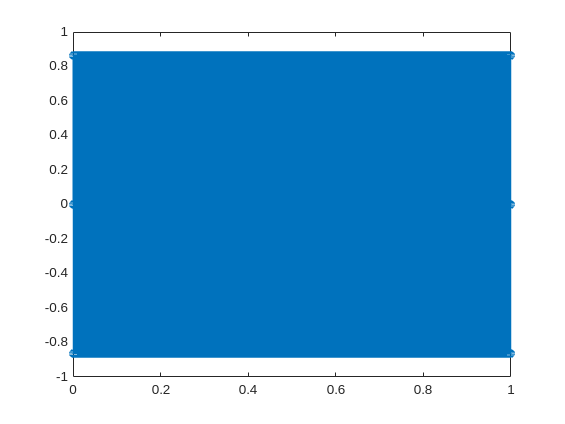

% INSERTE EL CÓDIGO AQUÍ:
f1 = 1000;
fs = 6e3;

A = 1;

num_segundos = 1;

% 't' está muestreado
t = 0:1/fs:num_segundos-1/fs; %----> debe ser un vector columna
t = t';

x_1000Hz = A*sin(2*pi*f1*t);

%indices = find(x_1000Hz == 0.866025);
%indices = indices(1:6);

figure;plot(t,x_1000Hz,'o-');shg

%los valores de xlim salen de dividir los indices de los 3 periodos
%(indices de los valores que valen '1') y dividirlos entre la fs
xlim([indices(1) indices(6)])

Index exceeds the number of array elements. Index must not exceed 3.

### 0.6 Resumen

En esta sección 0 hemos:

- repasado conceptos básicos de Matlab.

- generado una sinusoide.

- relacionado cada muestra con su instante de muestreo.

## 1. Procesado localizado (procesado por tramas, *frame processing*)

Si las características de una señal varían a lo largo del tiempo, suele ser interesante poder observar esos cambios. 

Vamos a programar una función que nos permita ir procesando trozo a trozo una señal. Una vez tengamos una estructura de código, podremos fácilmente ir incluyendo qué característica nos interesa calcular en cada momento.

### 1.1 Estructura de código para procesar tramas

En vez de manejar una señal complicada, con muchas muestras, vamos a usar una señal muy corta y sencilla, que nos permitirá comprobar si la estructura que programamos es correcta.

La señal de test será la siguiente:

xTest = (10:10:100)';

Representará 10 muestras, con valores crecientes.

La idea es dividir esta señal en lo que vamos a denominar "tramas". El ejemplo de la figura es una división en tramas de 3 muestras:

Crea una función nueva llamada *FrameProcessing,* con la siguiente cabecera:

*                function processedSignal = FrameProcessing(signal,Nframe,Noverlap)*

*Signal *es la variable que va a ser procesada y *Nframe* es el tamaño de trama. La variable *Noverlap *se usará en la próxima sección, de momento le daremos siempre un valor = 0.

Incluye estas líneas en el cuerpo de la función y complétalas:

                *% Length of signal to be processed*

                *Nsignal = ?????*

                *% Processed signal buffer*

                *processedSignal = [];*

                *% Number of frames to be processed (rough estimation)*

                *totalNframes = ?????;*

Probemos ahora si funciona según lo previsto. Al usar como entrada:

*             >> processedSignal = FrameProcessing(xTest,3,0);*

deberíamos haber inicializado correctamente esas variables de la función a estos valores:

            *    Nsignal ---> 10*

            *    processedSignal ---> []*

*                 totalNframes ---> 3*

El número total de tramas a procesar debe ser, obviamente, un valor entero positivo. 

A continuación de las líneas anteriores, vamos a añadir lo que sería la iteración a lo largo de la señal para ir aislando cada trama:

                    *% Iterate all frames*

                    *for frameNumber = 1:totalNframes*

                    *        % Frame starts here*

                    *        frameBegin = ****?????***

                    *         % Frame ends here*

                    *        frameEnd = ****?????***

                    *        % Signal contained in frame*

                    *        frameSignal = ****?????***

            *                disp(['Frame number ' num2str(frameNumber) '.....   ' num2str(frameSignal')]);*

*                        end*

Como debemos hacer al programar cualquier variación sustancial, probemos si funciona. 

Al llamar a la función con estos valores:

    *                  >> processedSignal = FrameProcessing(xTest,3,0);*

deberíamos obtener a la salida:

                    *Frame number 1.....   10  20  30*

            *        Frame number 2.....   40  50  60*

            *        Frame number 3.....   70  80  90*

Al llamar a la función con estos valores:

    *                >> processedSignal = FrameProcessing(xTest,4,0);*

deberíamos obtener a la salida:

                   *Frame number 1.....   10  20  30  40*

*                   Frame number 2.....   50  60 70  80*

Al llamar a la función con estos valores:

    *    >> processedSignal = FrameProcessing(xTest,5,0);*

deberíamos obtener a la salida:

        *Frame number 1.....   10  20  30  40  50*

        *Frame number 2.....   60   70   80   90  100*

¿Por qué a veces no aparecen los últimos valores de la señal? ¿Tiene sentido dejarlos fuera del procesado?

% Es debido a el redondeo que se aplica al hacer esta operación puede que
% sea hacia "abajo" lo que haria que haya menos frames

%Si que tiene sentido dejarlos fuera del procesado, porque sino los tamaños
%de los vectores serían distintos

### 1.2 Incorporando un solape entre tramas adyacentes

A la hora de observar cómo varían esas características, hay veces que es interesante que las tramas consecutivas se solapen entre sí, de forma que las variaciones se muestren de una forma suave, sin saltos bruscos. O, también, puede ser necesario trabajar con varias tramas a la vez para poder mejorar la calidad del resultado. Todo esto lo veremos más adelante, trabajando sobre diversas señales, pero vamos a dejar lista nuestra estructura de código para que pueda funcionar de ese modo usando la variable de entrada *Noverlap*.

 El ejemplo de la figura es una división en tramas de 3 muestras, con un solape de 1 muestra (la marcada por un círculo):

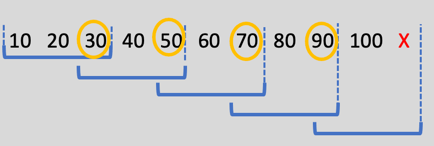

Modifica estas líneas para que las tramas se generen según lo esperado:

                *% Number of frames to be processed (rough estimation)*

                *totalNframes = ?????;*

            *    % Frame starts here*

            *    frameBegin = ****?????***

Hagamos la prueba de funcionamiento. 

Al llamar a la función con estos valores:

    *            >> processedSignal = FrameProcessing(xTest,3,0);*

deberíamos obtener a la salida:

        *        Frame number 1.....   10  20  30*

        *        Frame number 2.....   40  50  60*

        *        Frame number 3.....   70  80  90*

que, obviamente, es el mismo resultado que obteníamos antes de incluir el solape, ya que el solape es igual a cero. Siempre es recomendable comprobar que un cambio relevante en el código funciona para los casos que ya hemos testeado.

Probemos si el solape no es nulo. 

Al llamar a la función con estos valores:

    *        >> processedSignal = FrameProcessing(xTest,3,1);*

deberíamos obtener a la salida:

                *Frame number 1.....   10  20  30*

        *        Frame number 2.....   30  40  50*

        *        Frame number 3.....   50  60  70*

        *        Frame number 4.....   70  80  90*

que es el caso representado en la figura anterior del texto.

Al llamar a la función con estos valores:

    *            >> processedSignal = FrameProcessing(xTest,3,2);*

deberíamos obtener a la salida:

                *Frame number 1.....   10  20  30*

        *        Frame number 2.....   20  30  40*

        *        Frame number 3.....   30  40  50*

        *        Frame number 4.....   40  50  60*

        *        Frame number 5.....   50  60  70*

        *        Frame number 6.....   60  70  80*

        *        Frame number 7.....   70  80  90*

        *        Frame number 8.....   80   90  100*

Una vez comprobado que la segmentación en tramas funciona correctamente, sólo nos queda completar la estructura de código que estamos preparando. Vamos a preparar el parámetro de salida e indicar en qué lugar haremos el procesado de cada trama. 

Después de estas líneas:

            *    % Signal contained in frame*

            *    frameSignal = ?????*

Añade:

            *    % Here comes the frame processing*

            *        processedFrame = frameSignal;*

            *    % Processed frame is added to the processed signal buffer*

            *    processedSignal = [processedSignal processedFrame];*

Más adelante, *processedFrame *la obtendremos modificando *frameSignal.*

Y comenta la salida por consola.    

    *           % disp(['Frame number ' num2str(frameNumber) '.....   ' num2str(frameSignal')]);*

Probemos este último cambio. 

Al llamar a la función con estos valores:

    *            >> processedSignal = FrameProcessing(xTest,3,1);*

no debería haber ninguna salida por consola.

Al visualizar por consola el valor del parámetro de salida

                >> *processedSignal*

deberíamos obtener:

                *processedSignal =*

                    *     10     30     50     70*

        *                 20     40     60     80*

        *                 30     50     70     90*

Recordad que siempre trabajamos con vectores columna, por lo que en la matriz de salida cada trama aparece en su columna correspondiente.

### 1.3 Resumen

En esta sección 1 hemos:

- programado nuestra propia estructura de código, *FrameProcessing(...)*, para poder procesar tramas de una señal. Incluye la posibilidad de forzar un solape entre tramas consecutivas.

## 2. Análisis de sonidos en el dominio del tiempo

### 2.1 Buscando información en la forma de onda

En la llamada forma de onda, que es la representación de la señal en el dominio del tiempo, podemos extraer información interesante. 

Carga la señal x2, generada usando la misma frecuencia de muestreo que estamos usando.

load x2.mat

Representa sólo los primeros 100 ms, con su eje de tiempos y usando *xlim*

%Insert code here

% El vector 't' tiene que ser de la misma longitud que la señal para poder
% representarlo
t = 1:1:length(x2);

% representar la señal
figure();plot(t,x2);

% Limitar las muestras (de 1 a 100)
xlim([1 100]);shg

Podemos representar dos señales a la vez si usamos el comando subplot, que subdivide la figura y nos indica en qué lugar se representará el comando plot que usemos. representa los primeros 100 ms en una figura arriba y los últimos 100 ms en otra figura debajo:

% Insert code here
t = 1:1:length(x2);
figure(); subplot(211); plot(t,x2);
xlim([1 100]);shg
subplot(212); plot(t,x2);

% con 't(end)' obtenemos el último elemento de el vector 't'
xlim([t(end)-100 t(end)]);shg

La señal parece que contiene componentes periódicos, aunque no se repite de forma exacta. ¿Qué períodos de repetición puedes encontrar? Haz uso de las herramientas de *zoom* y de *data tip* que tienes en la propia gráfica de Matlab.

Como puedes comprobar, hay periodicidades que se observan fácilmente y otras no tanto.

### 2.2 Resumen

En esta sección 2 hemos:

- observado la forma de onda de la señal en el tiempo para intentar observar si hay periodicidades en una señal e intentar estimarlas.

## 3. Análisis de sonidos en el dominio de la frecuencia

### 3.1 DFT vs fft

Aunque en la llamada forma de onda podemos extraer información muy interesante, hay otras características que son más complicadas de observar. El llamado espectro de potencia en frecuencia nos da información sobre qué componentes tienen energía significativa en la señal que analizamos.

Lo podemos calcular haciendo uso de la DFT (Transformada Discreta de Fourier). En Matlab la DFT se calcula usando la función *fft*. Se denomina así porque FFT es el acrónimo de Fast Fourier Transform, que es un algoritmo de cálculo muy rápido para poder hacer esa transformación. De hecho ese algoritmo es muy eficiente con potencias de 2, por lo que de ahora en adelante intentaremos usar longitudes que lo sean.

Veamos qué ocurre cuando usamos el tono de 1 kHz que tenemos en la señal x_1kHz para calcular y representar la DFT de las primeras 128 muestras (128 es 2^7).

X_1kHz = fft(x_1kHz,128);

Unrecognized function or variable 'x_1kHz'.

figure(); plot(X_1kHz);shg

% No se parece a un espectro de frecuencia, porque la señal es compleja (compleja = numeros complejos),
% entonces muestra en el eje 'x' los valores reales y en el 'y' los
% imaginarios

¿Qué información obtienes de esa figura? ¿Se parece a un espectro de frecuencia? ¿Por qué?

Arregla el problema y dibuja la estima del espectro en frecuencia.

% INSERTE EL CÓDIGO AQUÍ

X_1kHz = fft(x_1000Hz,2^7);
figure(); plot(abs(X_1kHz));shg

% hacer el módulo -> abs(X_1kHz)

La función fft devuelve los valores de la DFT entre 0 y 2pi en la forma [0,2pi).

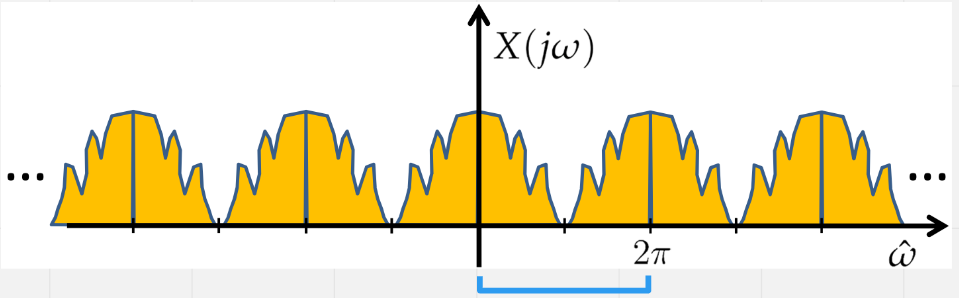

Como la señal es real, su transformada es par y habitualmente nos interesa representar solamente la parte que tiene una interpretación física, no la asociada a las frecuencias negativas. El primer elemento de la salida de la función *fft* se corresponde con la frecuencia f=0. Después le siguen los valores correspondientes a las frecuencias positivas hasta el valor inmediatamente anterior al correspondiente a la frecuencia de muestreo. Para el eje de frecuencias angulares normalizado, el elemento n-ésimo se calcula como $\frac{2\pi}{N}n$. Por ejemplo, para N = 8, el vector estaría formado por los elementos:

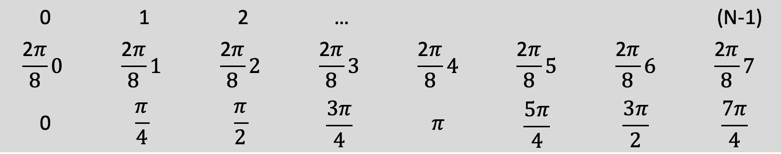

Para representar las frecuencias positivas del espectro nos interesan los primeros N/2+1 valores, que son los que habitualmente representamos.

Crea un eje de frecuencias adecuado, en Hz, y representa solamente esos N/2+1 primeros puntos, usando *plot* y la opción* '-o'*.

% % INSERTE EL CÓDIGO AQUÍ
% la fs son 6000Hz porque sabemos a qué frecuencia muestreamos (workspace),
% si no sabemos a qué frecuencia está muestreada una señal no la podemos
% obtener, ya que sólo sería un vector con valores "sueltos"
fs = 6000;

% Número de puntos que cogemos de la señal en el tiempo y número de muestra
% que usa para calcular la DFT
Nfft = 128;

% Como queremos coger sólo los N/2 + 1 elementos:
N_util = (Nfft/2) + 1;

% La N_util es un escalar y esto un vector
% Cogemos desde 0 hasta N_util-1 pq sino no tendríamos la componente
% contínua
vector_N_util = 0:N_util-1;

% (Fs*n)/N siendo Fs la "resolución espectral" (podría ser 2pi)
% RESOLUCIÓN ESPECTRAL -> DISTANCIA ENTRE LOS COMPONENTES FRECUENCIALES 
eje_freq = (vector_N_util*fs)/Nfft;


% Las señales tienen que ser de la misma longitud
figure(); plot(eje_freq,abs(X_1kHz(1:length(eje_freq))),'-o');shg


¿Coincide el valor del máximo con la frecuencia del tono? ¿Por qué? ¿Podrías mejorar el resultado para que se aproxime más?

% INSERTE EL CÓDIGO AQUÍ

% Si que podriamos mejorar el resultado usando más muestas (Nfft)

**EXTRA:**

Si quisiéramos observar la DFT centrada en el origen, entonces podríamos usar la función *fftshift*, que nos devolvería estos valores:

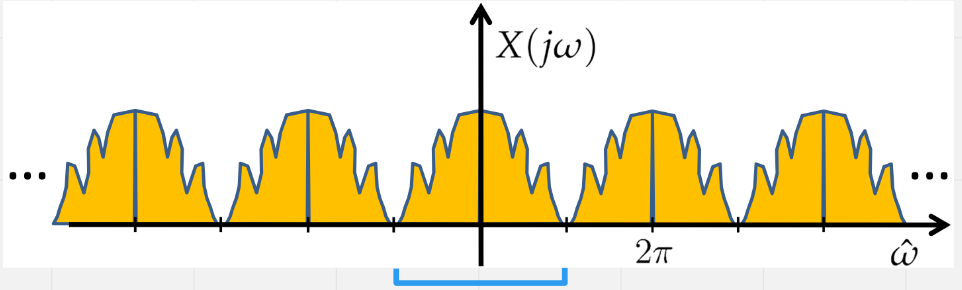

Prueba a representar el espectro completo de la señal usando *fftshift* y el eje de frecuencias correcto.

### 3.2 Periodograma: estimador de la Densidad Espectral de Potencia (PSD)

El módulo de la DFT no es una estima del espectro de potencia, sino una versión afectada por una escala. Un estimador del espectro de potencia es el llamado periodograma, que se define así:


$$periodograma(f) = \frac{1}{Lf_s}\left|\sum_{n=0}^{L-1}x[n]e^{-j2\pi f\frac{n}{f_s}}\right|^2,$$
 

donde *L* es el tamaño de la DFT y *fs* es la frecuencia de muestreo. Es decir, el periodograma se calcula como el módulo de la DFT al cuadrado, multiplicado por el factor *1/(L*fs)*.

Crea una función nueva con esta cabecera:

            *function outputPeriodogram = MyPeriodogram(signal,Nfft,f_s);*

y completa estas líneas en el cuerpo de la función para que devuelva el periodograma de tamaño Nfft/2+1:

*            % Cropped signal*

*            x = signal(1:Nfft);*

*            outputPeriodogram = ?????*

Probemos ahora si funciona según lo previsto. Al usar como entrada:

        *    >> outputPeriodogram = MyPeriodogram(x_1kHz,128,6e3);*

deberíamos tener una señal de salida de tamaño 65x1

*            >> size(outputPeriodogram)*

*            ans =*

*                     65     1*

con los siguientes valores iniciales:

        *    >> outputPeriodogram(1:3)*

            *ans =          *

*               1.0e-05 **

*                0.0977*

*                0.0986*

*                0.1015*

Prueba ahora la función con la señal x2, de la muestra 20e3 hasta la muestra 25e3 y dibuja el resultado con una ventana de 256 muestras para calcular la DFT. ¿Qué duración en segundos tiene este tamaño de ventana para calcular el periodograma?

% Numero de muestras
Nfft = 256;

% Distancia entre muestras en el espectro de frecuencia 
resolucionDFT = 6e3/Nfft;

% Se calcula el periodograma desde las muestras 20e3 hasta 25e3 con fs=6e3
outputPeriodogram = MyPeriodogram(x2(20e3:25e3),Nfft,6e3); 

% Para elegir sólo las muestras que queremos
N_util = (Nfft/2) + 1;
vector_N_util = 0:N_util-1;

% Los valores frecuenciales que vamos a representar (vector de escalares
% (1,2,3...) la resolucionDFT que es la distancia entre muestras
eje_freq = vector_N_util*resolucionDFT;

figure(); plot(eje_freq, outputPeriodogram,'-o');shg

duracionNfft = Nfft/6e3;

Repite lo mismo para el tramo de la muestra 1e3 hasta la muestra 6e3.

% INSERTE EL CÓDIGO AQUÍ

Nfft = 256;

% Numero muestras 
resolucionDFT = 6e3/Nfft;
outputPeriodogram = MyPeriodogram(x2(1e3:6e3),Nfft,6e3); 

N_util = (Nfft/2) + 1;
vector_N_util = 0:N_util-1;
eje_freq = vector_N_util*resolucionDFT;

figure(); plot(eje_freq, outputPeriodogram,'-o');shg

duracionNfft = Nfft/6e3;

¿De qué trozo de la señal x2 estamos procesando y representando su resultado en cada caso? ¿Se están utilizando las 5000 muestras de las señales para obtener el periodograma? ¿Por qué?

% INSERTE EL CÓDIGO AQUÍ

% Estamos tomando los 256 (Nfft) primeros valores desde la cota inferior.

% No se están usando las 5000 muestras por que se cogen sólo las 256
muestras 


### 3.3 Método de Welch: mejora de la estimación del espectro

El periodograma es un estimador que sufre un error con una varianza grande en la estimación de la densidad espectral de energía. Pero su sencillez hace que sea muy usado, aunque suele combinarse con dos acciones:

- **Enventanado**: trabajar sólo con un segmento de Nfft muestras de la señal equivale a multiplicar la señal completa por lo que se denomina una ventana rectangular. Esta ventana es una señal en la que todos sus valores son 0, salvo los que corresponden a las Nfft muestras que usamos, que tendrían un valor 1. Las discontinuidades en los extremos de este segmento no forman parte de la señal que analizamos, pero provocarán una distorsión en nuestra estima. Usar un tipo de ventana (Hamming, Blackman, etc.) que atenúe estas discontinuidades suele ser muy eficaz. Es lo que se denomina un *periodograma modificado*.

- **Solapamiento**: el usar ventanas que atenúen los extremos hace que las muestras de la señal afectadas aporten poca información al estimador del espectro, lo que puede eliminar información importante. La forma más habitual de solucionarlo es hacer que las ventanas adyacentes se vayan solapando entre ellas, para dar una importancia similar a todas las muestras analizadas.

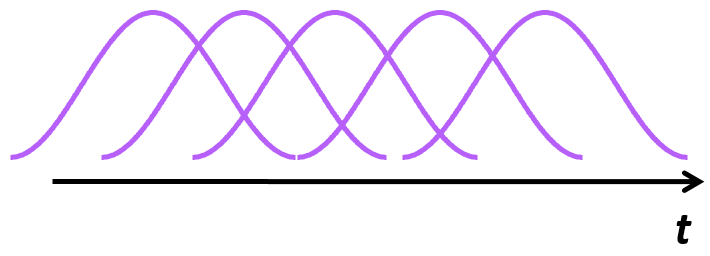

Si usamos estas dos técnicas, enventanado y solapamiento, y, además, vamos promediando los resultados de varias ventanas, entonces tenemos el llamado ***método de Welch***. Este promediado reduce la varianza en el error que cometemos al estimar el espectro de la señal. Lo comprobaremos en cuanto programemos nuestra herramienta para calcularlo.

Como ya hemos comprobado que nuestra estructura básica de código, que tenemos en la función *FrameProcessing,* es robusta y funciona, podemos añadir nuestro primer procesado. 

 Recordemos que ya es capaz de usar segmentos de señal (tramas) y crearlos usando un solapamiento. Sólo nos falta poder multiplicar cada trama por un tipo de ventana y añadir el promediado de varios periodogramas que vayamos obteniendo con la función que también hemos programado: *MyPeriodogram()*.

Salva la función *FrameProcessing* a un archivo llamado *FramePeriodogram*, y modifica su cabecera:

*            function processedSignal = FramePeriodogram(signal,Nframe, Noverlap, windowType, f_s)*

Vamos a ir incluyendo en esta función lo que necesitamos. Primero, el enventanado. El **tamaño** de la ventana ya lo tenemos en cuenta, *Nframe*, porque vamos a considerar, por sencillez, que coincide con el tamaño de la DFT, *Nfft*. Nos quedaría multiplicar por un **tipo** de ventana. Podríamos hacerlo antes de llamar a nuestra función *MyPeriodogram*, pero parece más lógico incluir ese paso dentro de la propia función *MyPeriodogram.* Guardamos una nueva versión de *MyPeriodogram* como *MyPeriodogramByFrames *y cambiamos su cabecera a:

            *function outputPeriodogram = MyPeriodogramByFrames(signal,Nfft,f_s,windowType);*

y dentro del cuerpo de la función:

            *% Window*

*            windowSignal = window(windowType,Nfft);*

*            windowedSignal = ?????;*

donde hacemos uso de la función *window* de Matlab. Usa help para consultar su documentación y los tipos de ventana que proporciona.

Ahora la variable a procesar es *windowedSignal*, sustituimos *x* por su nuevo nombre en el cálculo del periodograma.

*            outputPeriodogram = ?????*

Si usamos la opción de vantana 'rectwin' debería darnos exactamente los mismos resultados que en nuestra versión anterior, ¿por qué?

Volviendo a la función *FramePeriodogram, *ahora sólo queda ir promediando los periodogramas que vayamos obteniendo de cada trama. Incluiremos el procesado del periodograma de cada trama aquí:

            *    % Here comes the frame processing*

*                processedFrame = MyPeriodogramByFrames(frameSignal,Nframe,f_s,windowType);*

Y, después del bucle for que itera por todas las tramas, calculando cada periodograma, incluiremos:

                *% Welch's method*

*                processedSignal = ?????*

Recordad que, al final de ese bucle *for*, en *processedSignal* tenéis una matriz con todos los periodogramas. Para encontrar el espectro promedio, usad la función *sum* de Matlab, prestando mucha atención a cómo sumáis los elementos.

Para comprobar que funciona, ejecutad:

            >> *welchOutput= FramePeriodogram(x_1kHz(1e3:5e3),256,128,'rectwin',6e3);*

Los primeros valores de *welchOutput* deberían ser:

                >> *welchOutput(1:3)               *

*                ans =               *

*                   1.0e-06 **

*                    0.9451*

*                    0.9465*

*                    0.9508*

Vamos a probar si el método de Welch funciona. Toma otra vez la señal x2, de la muestra 20e3 hasta la muestra 25e3 y dibuja el resultado de un solo periodograma, con una ventana, para calcular la DFT, de 256 puntos. Dibuja en otra gráfica la salida del Método de Welch con el mismo tamaño de DFT y un solape del 50% entre tramas consecutivas.

Nfft = 256;
resolucionDFT = fs/Nfft;

outputPeriodogram = MyPeriodogram(x2(20e3:25e3),Nfft,6e3);

N_util = (Nfft/2) + 1;
vector_N_util = 0:N_util-1;
eje_freq = vector_N_util * resolucionDFT;

figure(); plot(eje_freq, outputPeriodogram,'-o'); title('periodogram 20e3-25e3');shg
welchOutput = FramePeriodogram(x2(20e3:25e3),Nfft,Nfft/2,'rectwin',6e3);
figure(); plot(eje_freq,welchOutput,'-'); title('Welch 20e3-25e3');shg

Si os fijáis y hacéis zoom una y otra vez sobre las frecuencias más altas podéis observar que existe energía que es imposible distinguir debido al gran rango dinámico que tiene el espectro de potencia. ¿Cuál es la relación entre el valor máximo del espectro y el valor menor?

% Calcular relación de valores max/min en welchOutput
relacion = max(welchOutput)/min(welchOutput)

Para manejar un rango dinámico tan grande se suele hacer uso del logaritmo en base 10, concretamente del decibelio, que lo definimos como 10*log10(relación de potencias). En nuestro caso, la salida de FramePeriodogram tiene unidades de potencia, por lo que podemos trabajar con 10*log10(welchOutput) y representarlo. Usando decibelios, dibuja otra vez las gráficas de la estima del espectro usando un solo periodograma y el método de Welch en la señal x2, de la muestra 20e3 hasta la muestra 25e3. Cuidado, asegúrate de usar la función del logaritmo en base 10, que es *log10*.

% INSERTE EL CÓDIGO AQUÍ
welchOutput = 10*log10(welchOutput);
figure(); plot(eje_freq,welchOutput,'-'); title('Welch 20e3-25e3');shg

¿Observas algún tono a mayores, además del que está en baja frecuencia? ¿Lo observas en ambas representaciones? ¿Qué aspecto tiene en ambas figuras el resto del espectro que contiene un ruido de nivel bajo?

Cuando hay componentes en frecuencia con unas características que prácticamente no varían en el tiempo, entonces un promediado de los espectros, método de Welch, hace que su estima sea más robusta. Un ruido aleatorio, al variar muchas características a lo largo del tiempo, se suele ver atenuado con respecto a una estimación usando un único periodograma. 

### 3.4 Tamaños y tipos de ventanas

Crea un vector con 64 ceros al comienzo, seguido por los valores de un tipo de ventana que te proporcione la función *window(...)* de Matlab, y acabando con otros 64 ceros al final. Dibuja los espectros solapados en una misma figura, con colores distintos, de varias ventanas: rectangular, Hamming, Blackman, etc. Usa el comando *hold*. Discute qué ocurre con sus lóbulos principal y secundarios y en qué circunstancias será mejor una u otra.

ventana_rect = [zeros(64,1) ; window('rectwin',64) ; zeros(64,1)];
ventana_Hamming = [zeros(64,1) ; window('hamming',64) ; zeros(64,1)];
ventana_Blackman = [zeros(64,1) ; window('blackman',64) ; zeros(64,1)];

plot(ventana_rect);hold on;
plot(ventana_Hamming); hold on;
plot(ventana_Blackman);

ventana_rect = abs(fft(ventana_rect,128));
ventana_Hamming_frec = abs(fft(ventana_Hamming,128));
ventana_Blackman = abs(fft(ventana_Blackman,128));

plot(0:128/2,ventana_rect(1:(128/2)+1)); hold on;
plot(0:128/2,ventana_Hamming_frec(1:(128/2)+1)); hold on;
plot(0:128/2,ventana_Blackman(1:(128/2)+1));

**EXTRA:**

Repite el estudio con el método de Welch y el mismo tamaño de DFT, sobre el tramo de señal x2(20e3:25e3), pero usando un tipo de ventana 'hamming'. ¿Observas diferencias? ¿cuál parece mejor? ¿por qué?

% INSERTE EL CÓDIGO AQUÍ

### 3.5 Resumen

En esta sección 3 hemos:

- usado la función *fft* para calcular la DFT (Transformada Discreta de Fourier).

- programado una función *MyPeriodogram(...)* para calcular un periodograma, que es una estimación del espectro de frecuencia (PSD, la Densidad Espectral de Potencia). Nuestra función permite usar distintos tamaños y tipos de ventana.

- usado nuestra estructura de código para programar el método de Welch en *FramePeriodogram(...)*, incorporando *MyPeriodogram(...)*, para promediar periodogramas sucesivos y obtener una estima más robusta.

- usado una representación en decibelios para apreciar mejor las componentes en frecuencia de una señal.

- usado este método para detectar tonos en medio de ruido aleatorio.

- usar distintas longitudes y tipos de ventana y analizar su comportamiento.

## 4. Analizando señales que varían sus características en el tiempo

Las señales no siempre mantienen sus características a lo largo del tiempo. De hecho, suele ser muy habitual que el sonido se componga de una mezcla de múltiples fuentes, que pueden aparecer y desaparecer, o ir cambiando sus características a lo largo del tiempo.

La forma de onda es, obviamente, una representación muy interesante para ver esos cambios, pero en muchos casos nos interesa trabajar en el dominio de la frecuencia, de ahí que hayamos preparado *FramePeriodogram(...)*. Pero... ¿y si cambian las características en frecuencia a lo largo del trozo de señal del que estamos estimando su espectro?

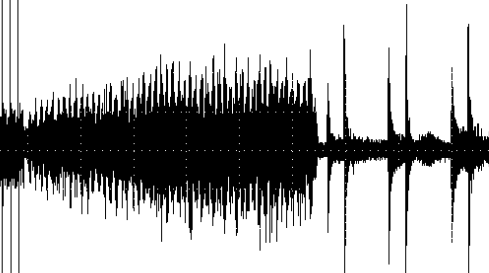

### 4.1 El espectrograma: representación simultánea tiempo-frecuencia

El espectrograma es una gráfica que permite visualizar cómo varía el comportamiento espectral de una señal con el tiempo. En el eje horizontal, se representa el paso del tiempo mientras que en el eje vertical, se representa la frecuencia. Un mapa de colores define cómo se representa el rango dinámico y a qué color corresponde cada valor. La mayor o menor concentración de energía se visualiza con la calidez del color; habitualmente, cuanto más cercano al rojo, mayor es la energía en esa zona. Si el mapa de color es en escala de grises, podemos optar, también, por asignar los valores más altos a los más oscuros. U otro mapa de color que elijamos.

Si lo pensamos con calma, nosotros ya vamos calculando estimas del espectro conforme avanza el tiempo en nuestra estructura básica de código, ya que dividimos en segmentos y calculamos cada periodograma. Además lo estamos haciendo con un solape entre tramas, por lo que programar un espectrograma a partir de lo que ya tenemos es muy sencillo.

Editamos la cabecera de la función FramePeriodogram(...) y la modificamos de la siguiente forma:

*            function [processedSignal,processedMatrix] = FramePeriodogram(signal,Nframe, Noverlap, windowType,f_s)*

¿Por qué hacemos esto? Recordad que esta función devolvía como parámetro de salida *processedSignal,* que era un vector que se correspondía con el promediado de los periodogramas que habíamos calculado dentro de la función. En realidad queremos usar todos esos periodogramas para irlos dibujando a lo largo del tiempo, de ahí el definir otro parámetro de salida, que va a ser una matriz con todos esos periodogramas.

Es fácil. Justo después del bucle *for*, antes de que modifiquemos el valor de *processedSignal, *resulta que tenemos justamente esa matriz que nos interesa. Incluímos una línea justo antes:

*              processedMatrix = processedSignal;*

*              % Welch's method*

*                processedSignal = ?????*

y así ya accedemos a esa matriz, por si nos interesa trabajar con ella.

Ahora vamos a utilizar la función *MySpectrogram Su cabecera es la siguiente:*

            *function MySpectrogram(processedMatrix,Nframe,Noverlap,f_s)*

y contiene este código:

            *%Spectrogram*

*            time_axis = 1/f_s * ( Nframe/2 : (Nframe-Noverlap) : length(processedMatrix(1,:))*(Nframe-Noverlap) )';*

    *         freq_axis = (0: f_s/Nframe: f_s/Nframe*(Nframe/2))';             *

*            figure;imagesc(time_axis,freq_axis,10*log10(processedMatrix));colormap(flipud(gray));colorbar;set(gca,'YDir','normal')*

            *figure;imagesc(time_axis,freq_axis,10*log10(processedMatrix));colormap(jet);colorbar;set(gca,'YDir','normal')*

            *xlabel('time [s]')*

            *ylabel('freq [Hz]')*

            *shg*

En primer lugar se crean los ejes en frecuencia y tiempo que usaremos, y con la función *imagesc *podemos representar los valores de la matriz en una imagen. Los valores que representaremos estarán en decibelios, para reducir su rango dinámico, y el mapa de color se define con la función *colormap*. En este caso hacemos que, por defecto, representemos en dos figuras distintas los espectrogramas en dos mapas de color distintos. Más adelante, podéis comentar la línea que se corresponda con el mapa de color que no vayáis a usar.

La línea *set(gca,'YDir','normal') *invierte el eje y para que el espectrograma que estamos representando tenga el mismo formato que el espectrograma generado con Matlab que utilizaremos en el siguiente apartado.

*Si ejecutáis estos comandos*

            *>> Nfft=256;*

*            >> Nsolape=Nfft/2;*

*            >> windowType = 'rectwin';*

*            >> f_s = 6e3;*

*            >> [welchOutput,welchMatrix]= FramePeriodogram(x2,Nfft,Nsolape,windowType,f_s);*

*            >> MySpectrogram(welchMatrix,Nfft,Nsolape,f_s);*

deberíais tener una salida similar a:

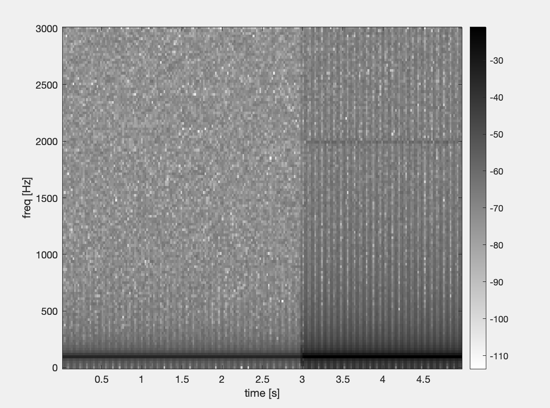     

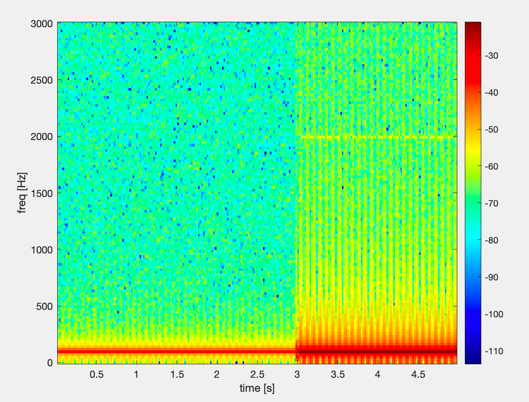

% INSERTE EL CÓDIGO AQUÍ

Nfft=256
Nsolape=Nfft/2;
windowType = 'rectwin';
f_s = 6e3;
[welchOutput,welchMatrix]= FramePeriodogram_ej4(x2,Nfft,Nsolape,windowType,f_s);
MySpectrogram(welchMatrix,Nfft,Nsolape,f_s);

Prueba a cambiar el tipo de ventana a 'hamming' y dibuja otra vez los espectrogramas de la señal x2, ¿hay diferencias? ¿por qué? ¿cuál parece más apropiado?

% INSERTE EL CÓDIGO AQUÍ

Nfft=256
Nsolape=Nfft/2;
windowType = 'hamming';
f_s = 6e3;
[welchOutput,welchMatrix]= FramePeriodogram(x2,Nfft,Nsolape,windowType,f_s);
MySpectrogram(welchMatrix,Nfft,Nsolape,f_s);


### 4.2 ¿Qué tamaño de ventana debemos usar?

Combinando nuestras dos herramientas, *FramePeriodogram(...)*, para tener una estima mejor del espectro de frecuencia en un tramo, y *MySpectrogram(...)* para poder observar variaciones de la energía en frecuencia a lo largo del tiempo, vamos a extraer características de varias señales de sonido. Recuerda que, por supuesto, también tenemos la posibilidad de observar la forma de onda para detectar posibles cambios en la energía a lo largo del tiempo.

Carga la señal audio1:

load audio1.mat

Aplica el método de Welch sobre la señal ***audio1*** al completo utilizando una ventana *hamming* de 1024 muestras, con un solape del 50%. 

% INSERTE EL CÓDIGO AQUÍ

Nfft = 1024;
Nsolape=Nfft/2;
windowType = 'hamming';
f_s = 6e3;

resolucionDFT = fs/Nfft;

N_util = (Nfft/2) + 1;
vector_N_util = 0:N_util-1;
eje_freq = vector_N_util * resolucionDFT;


[welchOutput,welchMatrix] = FramePeriodogram_ej4(audio1,Nfft,Nsolape,windowType,f_s);
MySpectrogram(welchMatrix,Nfft,Nsolape,f_s);
figure(); plot(eje_freq,welchOutput,'-'); title('Welch');shg

Repite esa estima del espectro sobre los últimos 0.5 segundos de la señal de audio. ¿Cuál es la diferencia respecto al resultado anterior?  ¿por qué ocurre esto? A la vista del espectro, ¿qué señal estamos analizando? Ayúdate del espectrograma y del estudio de la forma de onda temporal.

% INSERTE EL CÓDIGO AQUÍ

Nfft = 1024;
Nsolape=Nfft/2;
windowType = 'hamming';
f_s = 6e3;

resolucionDFT = fs/Nfft;

N_util = (Nfft/2) + 1;
vector_N_util = 0:N_util-1;
eje_freq = vector_N_util * resolucionDFT;

%figure(); plot(eje_freq, outputPeriodogram,'-o'); title('periodogram 20e3-25e3');shg
[welchOutput,welchMatrix] = FramePeriodogram_ej4(audio1(length(audio1)-(f_s/2) : length(audio1)),Nfft,Nsolape,windowType,f_s);
MySpectrogram(welchMatrix,Nfft,Nsolape,f_s);
figure(); plot(eje_freq,welchOutput,'-'); title('Welch 20e3-25e3');shg

Usando la forma de onda identifica cuál es la frecuencia del tono al comienzo de la señal y cuál es al final de la señal. Contrasta ese resultado con el que proporciona el espectro en frecuencia.

% INSERTE EL CÓDIGO AQUÍ

% Al principio del audio la frecuencia es de unos 74Hz porque 


¿En realidad podemos estar seguros de que nuestra representación en frecuencia es la adecuada? ¿el archivo *.mat*  tiene información de con qué frecuencia de muestreo se obtuvo esa señal digital?

% Escribe tu respuesta:
%
%
%si
%

Vamos a suponer que la frecuencia de muestreo con la que fue generada la señal *audio1* es de 16 kHz. 

Calcula otra vez cuál es la frecuencia del tono al comienzo de la señal y cuál es al final de la señal. ¿Qué relación tienen con las anteriores que calculaste antes?

% INSERTE CÓDIGO AQUÍ
%
% Respuesta:


Sobre el primer segundo de la señal *audio1, *estima el espectro probando distintos tamaños de la ventana que usas para calcular cada DFT. Usa los tamaños 32, 64, 128 y 2048.

¿Algún problema? ¿alguno de estos tamaños de ventana no permite calcular la frecuencia del tono? ¿por qué? Usa la forma de onda para razonarlo.

¿Qué duración temporal en segundos tiene la ventana de 32 muestras? ¿Y la de 2048?

¿Son válidos los tamaños de ventana anteriores para trabajar en el último segundo de *audio1*? ¿por qué?

% Inserte aquí el código

### 4.3 ¿Qué tipo de ventana debemos usar? Encontremos características relevantes en un sonido "real".

Carga la señal audio2:

% INSERTE CÓDIGO AQUÍ

Dibuja su forma de onda

% INSERTE CÓDIGO AQUÍ

Vamos a suponer que la frecuencia de muestreo con la que fue generada la señal *audio2 *es, también, de 16 kHz. 

Vemos que la señal es muy cambiante, con partes de mucha energía y partes con muy poca. 

Reproduce la señal por los auriculares usando:

         *>> soundsc(audio2);*

¿Qué sonido es? ¿qué características puedes deducir al escucharlo? ¿notas algo raro?

Revisa la ayuda de la función soundsc() e intenta escucharlo correctamente.

% INSERTE CÓDIGO AQUÍ

Representa la señal audio2 y haz zoom en la gráfica para visualizar el intervalo 6700-7400 (muestras). Es una parte de una vocal, con una estructura que podemos denominar seudoperiódica. No hay una periodicidad perfecta, pero hay un patrón de repetición evidente.

% INSERTE CÓDIGO AQUÍ

De hecho, al ser una vocal en una voz humana, muestra un patrón armónico, donde se deben observar periodicidades en una llamada frecuencia fundamental (f0) y en una serie de armónicos (múltiplos enteros) de ésta. 

¿Puedes calcular la frecuencia fundamental a partir de la forma de onda? ¿Y alguno de los armónicos?

esto sería el resultado del análisis...   

% INSERTE CÓDIGO AQUÍ

Vamos a calcular el espectro de frecuencia en ese mismo intervalo. Añade esta línea antes de los cálculos:

            *intervalo= 6700:7400;*

y añade esto después de usar la función plot:

*            title(['audio2(' int2str(intervalo(1)) ':' int2str(intervalo(end))  ') Nfft/type: ' int2str(Nfft) '/' windowType]);*

De esta forma puedes saber qué parámetros estás cambiando en cada figura si analizas la señal *audio2(intervalo)*. Modifica el texto contenido en *title* a tu gusto.

Prueba con una DFT de 256 muestras y compara el usar ventana rectangular o Hamming a la hora de observar el patrón armónico y calcular la frecuencia fundamental y las frecuencias de sus armónicos. 

¿Coinciden los valores con los estimados a partir de la forma de onda?

% INSERTE CÓDIGO AQUÍ

Prueba lo mismo con una DFT de 128 muestras.

% INSERTE CÓDIGO AQUÍ

Prueba lo mismo con una DFT de 64 muestras.

% INSERTE CÓDIGO AQUÍ

¿En todos los casos podemos extraer la frecuencia fundamental?

Si hay algún caso donde no puedas extraer esa información, ¿puedes encontrar otra información interesante en ese espectro?

% Respuesta:

Calcula el espectrograma de ese intervalo, usando una DFT de 256 muestras.

¿Cambia la frecuencia fundamental del comienzo al final de ese tramo?

% INSERTE CÓDIGO AQUÍ

Calcula el espectrograma de toda la señal *audio2*, usando una DFT de 256 muestras.

¿Cambia la frecuencia fundamental del comienzo al final de la señal? ¿por qué?

Si hay cambio, ¿qué información contiene ese cambio, cómo se denomina?

¿Observas alguna otra información interesante?

¿Qué tipo de espectrograma tenemos aquí, de banda estrecha o de banda ancha? ¿por qué?

% INSERTE CÓDIGO AQUÍ

Calcula el espectrograma de toda la señal *audio2*, usando una DFT de 32 muestras.

¿Cambia la frecuencia fundamental del comienzo al final de la señal? ¿por qué?

Si hay cambio, ¿qué información contiene ese cambio, cómo se denomina?

¿Observas alguna otra información interesante?

¿Qué tipo de espectrograma tenemos aquí, de banda estrecha o de banda ancha? ¿por qué?

% INSERTE CÓDIGO AQUÍ

Usa los ajustes de la gráfica en la interfaz de usuario (UI) de Matlab para identificar y dibujar un trozo donde se observe un transitorio (/p/, /k/) en la forma de onda. 

¿Puedes identificar transitorios si observas el espectrograma? ¿por qué?

% INSERTE CÓDIGO AQUÍ

Usa los ajustes de la gráfica en la interfaz de usuario (UI) de Matlab para identificar y dibujar un trozo donde se observe una parte muy ruidosa (aleatoria) (/s/) en la forma de onda.

¿Puedes identificar zonas ruidosas (aleatorias) si observas el espectrograma? ¿por qué?

% INSERTE CÓDIGO AQUÍ

**Extra:**

*La evolución de los dos primeros máximos locales de la envolvente del espectro (formantes) en el espectrograma de banda ancha, nos va indicando el movimiento del tracto vocal cuando pronunciamos vocales. El tracto vocal comprende la cavidad oral (desde la laringe hasta los labios) y la cavidad nasal acoplada a la oral a través del velo del paladar; puede considerarse como un filtro con cinco zonas de resonancias relevantes (5 formantes) por el que pasa el aire que viene de los pulmones. Si las cuerdas vocales están vibrando,aparecen líneas horizontales en el espectrograma de banda estrecha. Para las vocales, los  dos formantes principales están en dos rangos de frecuencia. En la siguiente figura, se observan unos promedios de las frecuencias de los dos primeros formantes de las cinco vocales del español.*

*Identifica los dos primeros formantes de las vocales de audio2 y comprueba que se corresponden con la vocal oída en la voz.*

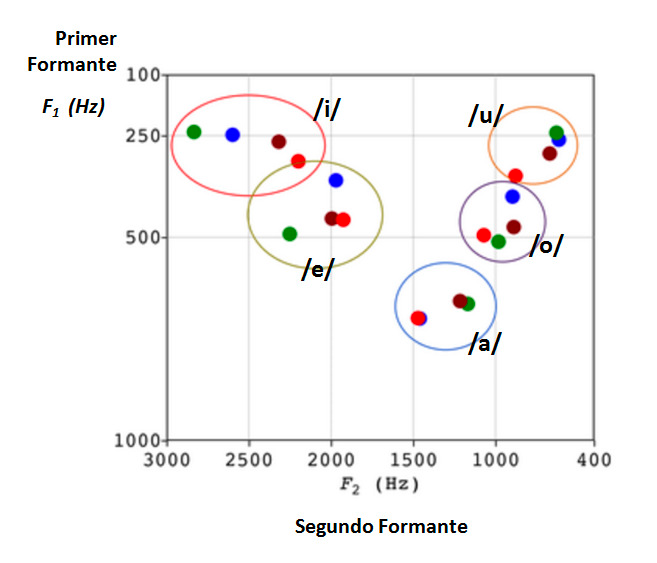

### 4.4 Resumen

Como podemos concluir, un análisis correcto de las señales de audio reales (de la *realidad*) requiere analizar:

-  La variación de la energía de la señal en el tiempo. Si es más o menos cambiante, si es constante o no. Además es importante identificar en el tiempo periodos de repetición, si existen.

- La variación de la energía en frecuencia. Si hay componentes tonales o no, si existen zonas ruidosas, si hay patrones armónicos o no, etc. También es importante identificar la posición precisa de los tonos en caso de haberlos.

- Variación de la energía en frecuencia a lo largo del tiempo (espectrogramas). Analizar los intervalos temporales con patrones armónicos, los de apariencia ruidosa, con bajas, medias o altas frecuencias. La variación de la frecuencia fundamental a lo largo del tiempo (como la entonación en la voz o la melodía en un instrumento) es otro elemento a tener en consideración.

En esta sección 4 hemos:

- programado una función *MySpectrogram(...)* para representar un **espectrograma**, que es una estimación de la variación temporal del espectro de frecuencia (PSD, la Densidad Espectral de Potencia). 

- alimentado esta función *MySpectrogram(...)* con resultados intermedios de nuestra función *FramePeriodogram(...).* Se añadió un parámetro de salida para obtenerlos.

- discutido la influencia del **tamaño** de ventana que usamos al hacer la estima espectral.

- constatado la importancia de saber siempre qué frecuencia de muestreo hemos usado al muestrear la señal que analizamos.

- discutido la influencia del **tipo** de ventana que usamos al hacer la estima espectral.

- investigado cómo identificar características relevantes de un sonido "real", como puede ser la voz humana.